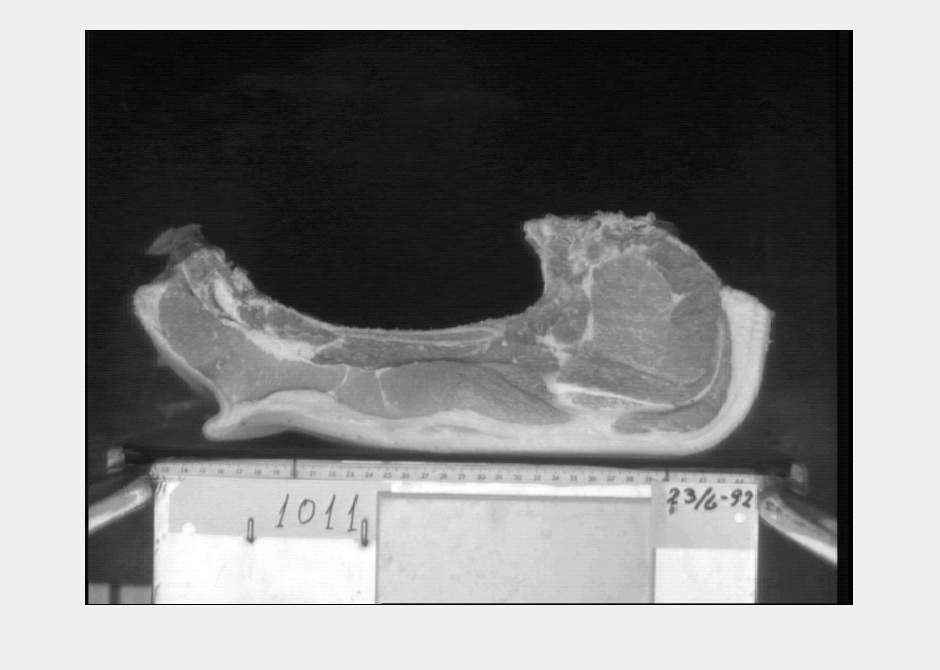

%clear all;
close all;
im = imcrop(imread('F1011flb.bmp'));

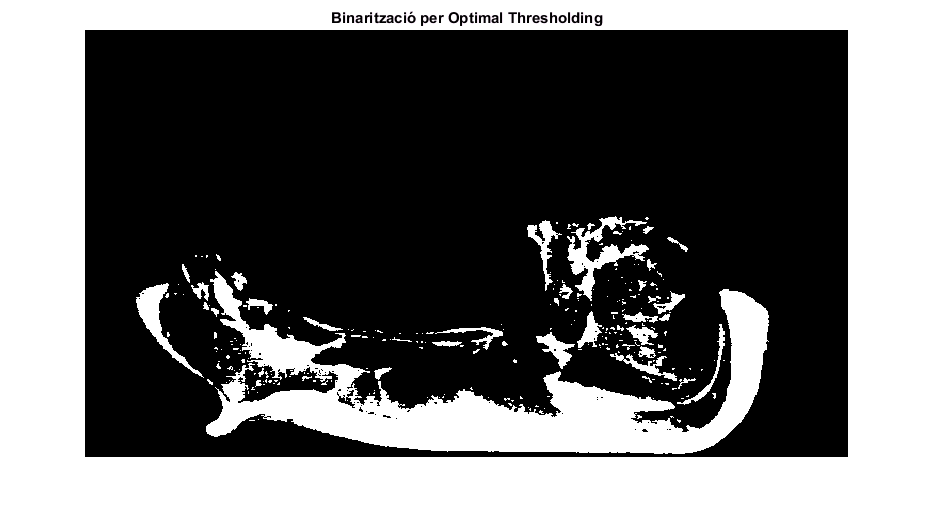

imshow(im)

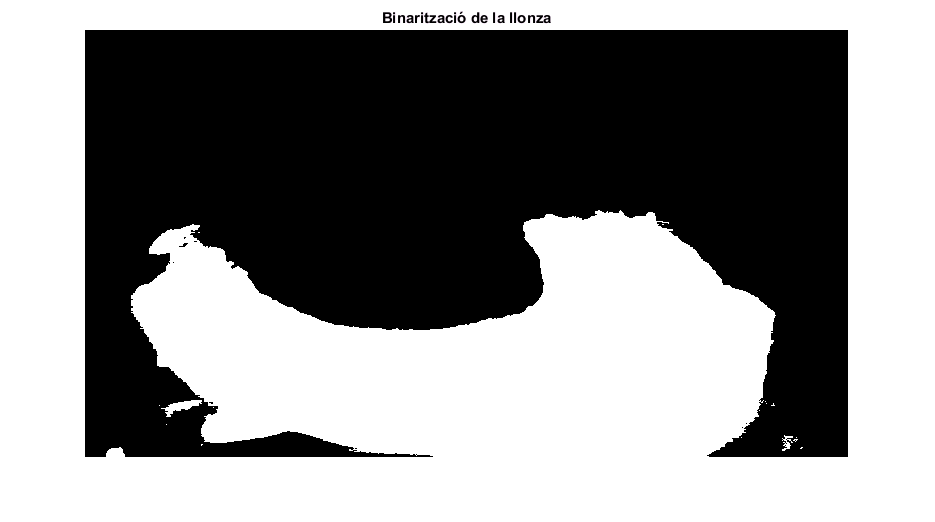

% TODO: RETALLAT? COM LLEGIR TOTES LES IMATGES?
% J = imcrop(im);
% imshow(J)

% 2) Implementar un petit programa que binaritzi les imatges a partir d’un llindar
% programable per l’usuari. Trobar el % de píxels de greix.
% El % de greix cal trobar-lo respecte dels píxels totals de la llonza. Per tant, abans de fer el
% càlcul cal eliminar els píxels del fons.

% Agafem només la llonza
llindar_llonza = 65/256;
im_llonza = im;
% im_llonza(im_llonza > llindar_llonza) = 255;
% im_llonza(im_llonza <= llindar_llonza) = 0;
im_llonza = imbinarize(im_llonza, llindar_llonza);
figure, imshow(im_llonza), title('Binarització de la llonza')

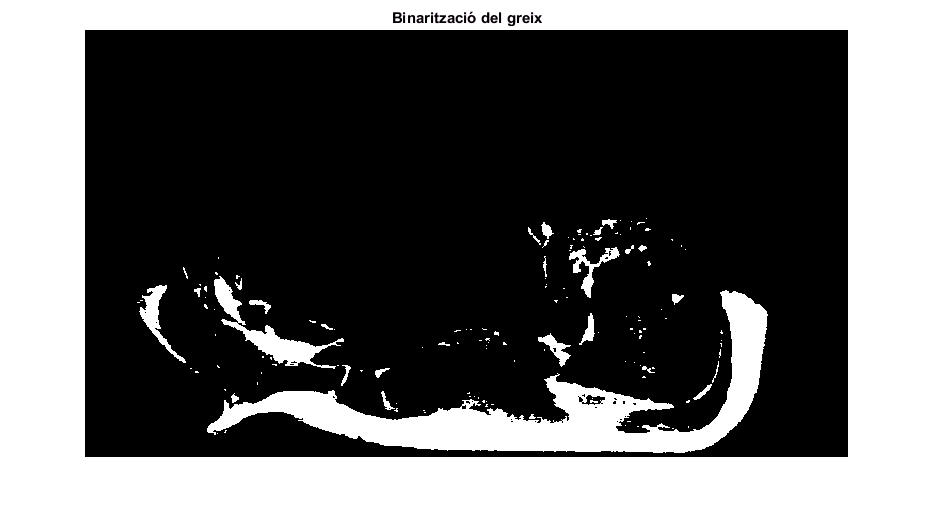


% Agafem només el greix
llindar_greix = 160/256;
im_greix = im;
% im_greix(im_greix>llindar_greix) = 255;
% im_greix(im_greix<=llindar_greix) = 0;
% Si utilitzem això hem de diidir el llindar per 256
im_greix = imbinarize(im_greix, llindar_greix);
figure, imshow(im_greix), title('Binarització del greix')


px_llonza = size(im_llonza(im_llonza), 1)

px_llonza = 103136

px_greix = size(im_greix(im_greix), 1)

px_greix = 27445


percentatge_greix = (px_greix/px_llonza) * 100

percentatge_greix = 26.6105

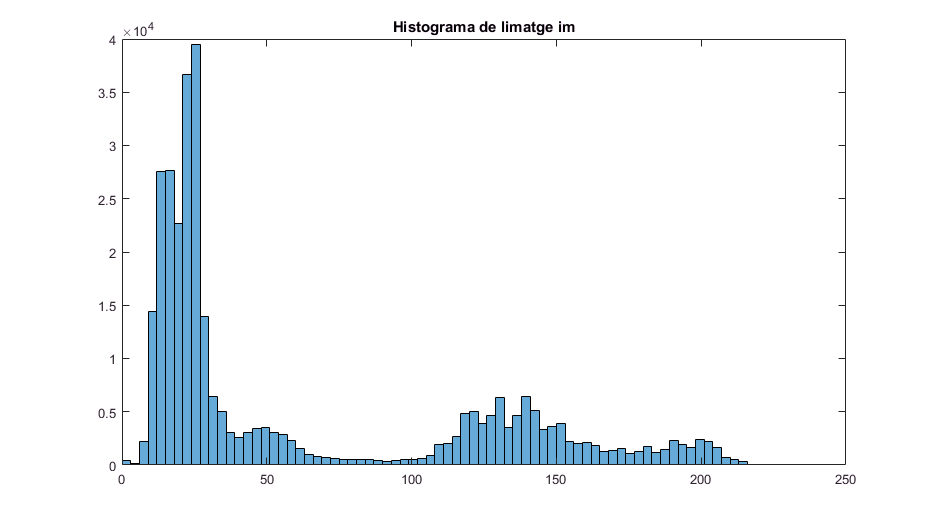


% 3) Extraure l’histograma de les imatges. Trobar el llindar a ull a partir de l’histograma.
% (Aquest histograma ens dona un interval de possibles llindars).
histogram(im), title('Histograma de limatge im');

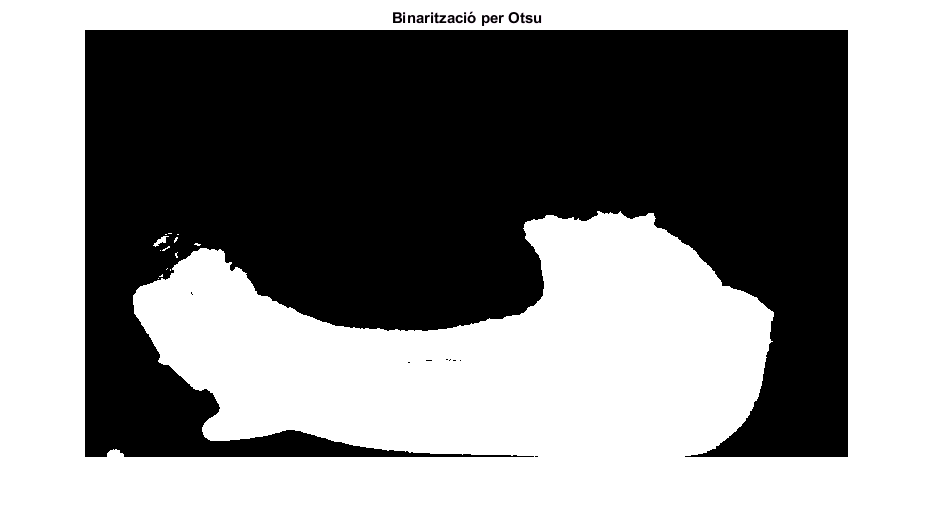


% 4) Trobar el llindar de forma automàtica. Podeu usar ‘graythresh’ de MATLAB. 
llindar_otsu = graythresh(im);
im_otsu = imbinarize(im,llindar_otsu);
figure, imshow(im_otsu), title('Binarització per Otsu')

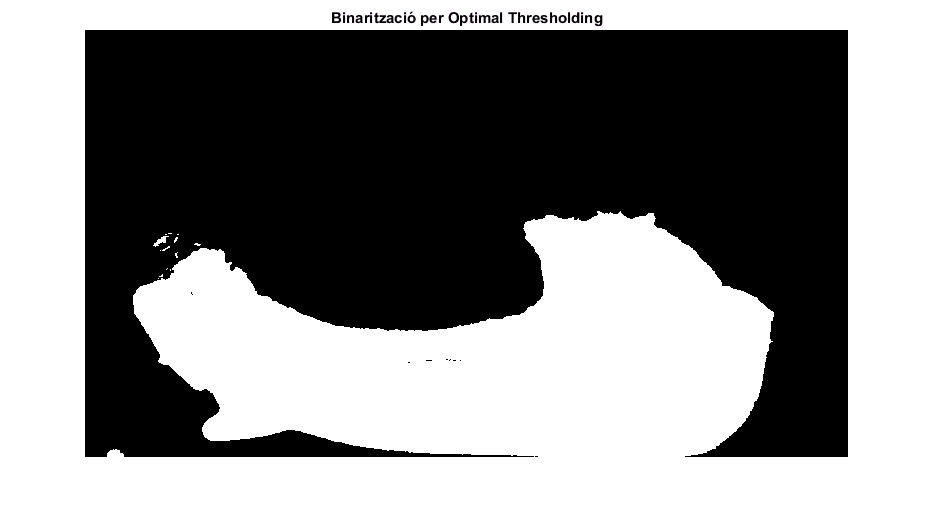


% 5) Trobar el llindar utilitzant algun altre mètode. Implementeu com a mínim dos mètodes diferents.
% Optimal thresholding => http://www.pvv.org/~perchrh/papers/datasyn/paper2/report.pdf
[rows, cols] = size(im);

Tt = 0;
%im = double(im);
all = sum(im(:));
background = im(1, 1) + im(rows, 1) + im(1, cols) + im(rows, cols);
uB = background/4;
uO = (all - background)/((cols * rows) - 4);
Tt_1 = (uB + uO)/2;

while Tt ~= Tt_1
    O = im(im >= Tt_1);
    B = im(im < Tt_1);
    
    uB = sum(B)/size(B, 1);
    uO = sum(O)/size(O, 1);
    
    Tt = Tt_1;
    Tt_1 = (uB + uO)/2;
end

llindar_optimal = Tt/256;
im_optimal = imbinarize(im, llindar_optimal);
figure, imshow(im_optimal), title('Binarització per Optimal Thresholding')

% Kapur thresholding => https://eprints.ucm.es/16932/1/Tesis_Master_Daniel_Martin_Carabias.pdf
H_max = -inf;
H = 0;
Tt = -1;
total_pixels = rows * cols;
for t = 1:256
    i = 0;
    j = t + 1;
    Hb = 0;
    Hw = 0;
    B = 0;
    for k = 1:t
        B = B + (size(im(im == k), 1)/total_pixels);
    end
    
    while i < t
        Pi = size(im(im == i), 1)/total_pixels;
        if Pi ~= 0
            Hb = Hb + (Pi/B * log(Pi/B));
        end
    
        Pj = size(im(im == j), 1)/total_pixels;
        if Pj ~= 0
            Hw = Hw + (Pj/(1 - B)) * log(Pj/(1 - B));
        end
        i = i + 1;
        j = j + 1;
    end
    
    H = -Hb + (-Hw);
    if H_max < H
        H_max = H;
        Tt = t;
    end
end
Tt

Tt = 8

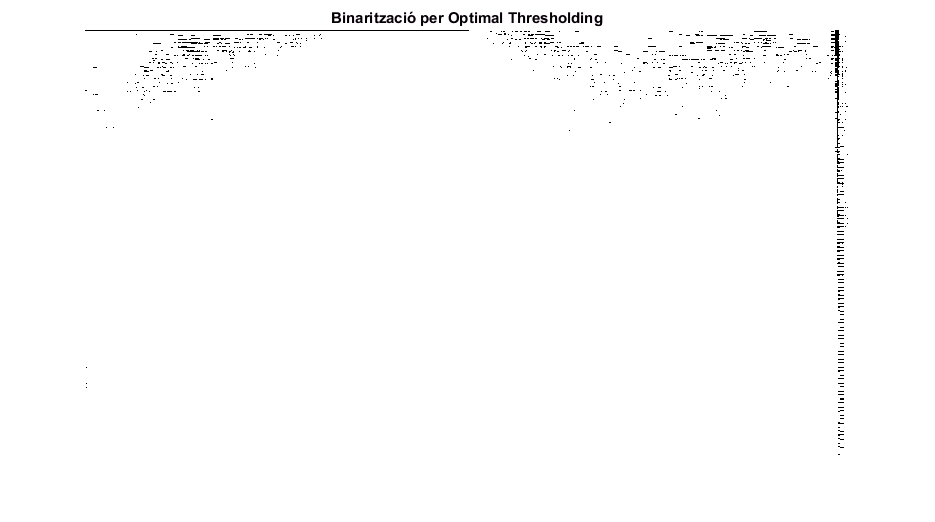

llindar_entropia = Tt/256;
im_entropia = imbinarize(im, llindar_entropia);
figure, imshow(im_entropia), title('Binarització per Optimal Thresholding')